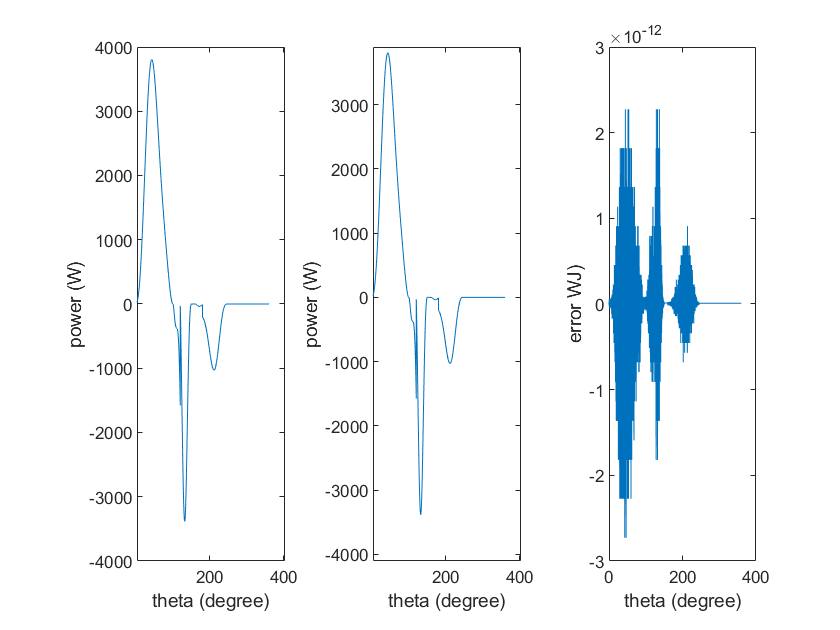

%%%%%%%%%%%%%%%%%%
% Matlab code bij taak cams
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear
close all
out = load("cam_design.mat");
out_no_exc = load("cam_no_exc.mat");

%extra gegevens definiëren
R_0 = (out.bcr + out.rof)*10^(-3);
N = out.normalforce_tot;
alpha = out.pressure_angle;
exc = out.exc*10^(-3);
S = out.S * 10^(-3);
R = sqrt(out.xpitch.^2 + out.ypitch.^2)*10^(-3);
% zonder eccentriciteit
R_0_no_exc = (out_no_exc.bcr + out_no_exc.rof)*10^(-3);
N_no_exc = out_no_exc.normalforce_tot;
alpha_no_exc = out_no_exc.pressure_angle;
S_no_exc = out_no_exc.S * 10^(-3);
R_no_exc = sqrt(out_no_exc.xpitch.^2 + out_no_exc.ypitch.^2)*10^(-3);
%test
% R_test = sqrt(out.xpitch.^2 + out.ypitch.^2)*10^(-3);
% R_err = R_test - R_0 - S;
% %plot(out.theta, R_err);
% DR = diff(R);

% vermogen met eccentriciteit = 0
P_no_exc2 = N_no_exc.*sin(alpha_no_exc).*(R_no_exc).*out_no_exc.w;

%vermogen met gekozen eccentriciteit
gamma = atan(exc ./ R);
P_exc2 = N.*cos(alpha).*((sqrt(R_0^2 - exc^2) + S).*tan(alpha) + exc)*out.w;

%fout op vermogen
P_err2 = P_no_exc2 - P_exc2;
figure
subplot(131)
plot(out.thetadegree, P_no_exc2)
subplot(132)
plot(out.thetadegree, P_exc2)
subplot(133)
plot(out.thetadegree, P_err2)

subplot(1,3,1)
xlim([3 403])
ylim([-4000 4000])
xlabel('theta (degree)')
ylabel('power (W)')
subplot(1,3,2)
xlim([3 403])
ylim([-4104 3896])
xlabel('theta (degree)')
ylabel('power (W)')
subplot(1,3,3)
xlabel('theta (degree)')

ylabel('error WJ)')


%gemiddeld vermogen
P_av2 = mean(P_exc2)

P_av2 = 232.9028

out.w % zijn dus allebei cte

ans = 62.8319

out.rpm

ans = 600

out.S

ans =          0    0.0000    0.0000    0.0001    0.0002    0.0003    0.0006    0.0009    0.0013    0.0019    0.0026    0.0035    0.0045    0.0058    0.0072    0.0089    0.0108    0.0129    0.0153    0.0181    0.0211    0.0244    0.0280    0.0320    0.0364    0.0411    0.0463    0.0518    0.0578    0.0642    0.0711    0.0784    0.0862    0.0946    0.1034    0.1128    0.1228    0.1333    0.1444    0.1561    0.1684    0.1814    0.1950    0.2092    0.2242    0.2398    0.2562    0.2732    0.2911    0.3096


Rb = out.bcr

Rb = 30

close all
K = 0.1

K = 0.1000

M = P_exc2./ out.w

M =    -0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0016    0.0017    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0036    0.0038    0.0041    0.0043    0.0046    0.0049    0.0052    0.0055    0.0058    0.0061    0.0064    0.0067    0.0071    0.0074    0.0078    0.0081    0.0085    0.0089    0.0092    0.0096


M_av = P_av2 ./ out.w

M_av = 3.7068

M_delta = M_av - M

M_delta =     3.7068    3.7068    3.7067    3.7067    3.7067    3.7067    3.7066    3.7066    3.7065    3.7064    3.7064    3.7063    3.7062    3.7061    3.7060    3.7059    3.7058    3.7056    3.7055    3.7053    3.7052    3.7050    3.7048    3.7047    3.7045    3.7043    3.7041    3.7039    3.7036    3.7034    3.7032    3.7029    3.7027    3.7024    3.7022    3.7019    3.7016    3.7013    3.7010    3.7007    3.7004    3.7000    3.6997    3.6994    3.6990    3.6987    3.6983    3.6979    3.6975    3.6971


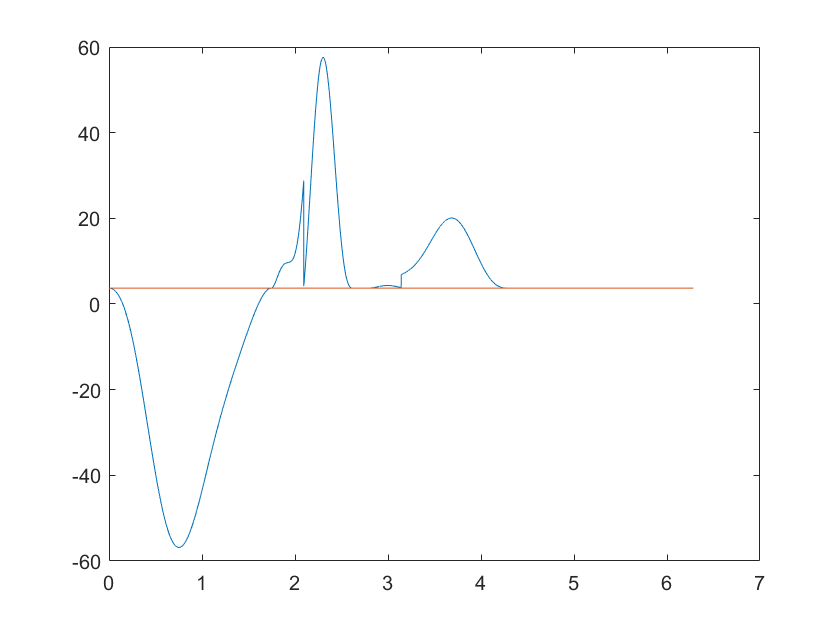

% dus altijd wnnr M > M_av vertraagt de cam en wnnr M < M_av versnelt de
% cam. M is hier het lastmoment dat verandert in de tijd en M_av stelt het
% veronderstelde geleverde vermogen door de motor voor. 

figure
plot(out.theta, M_delta, out.theta,ones(size(out.theta)) * M_av)

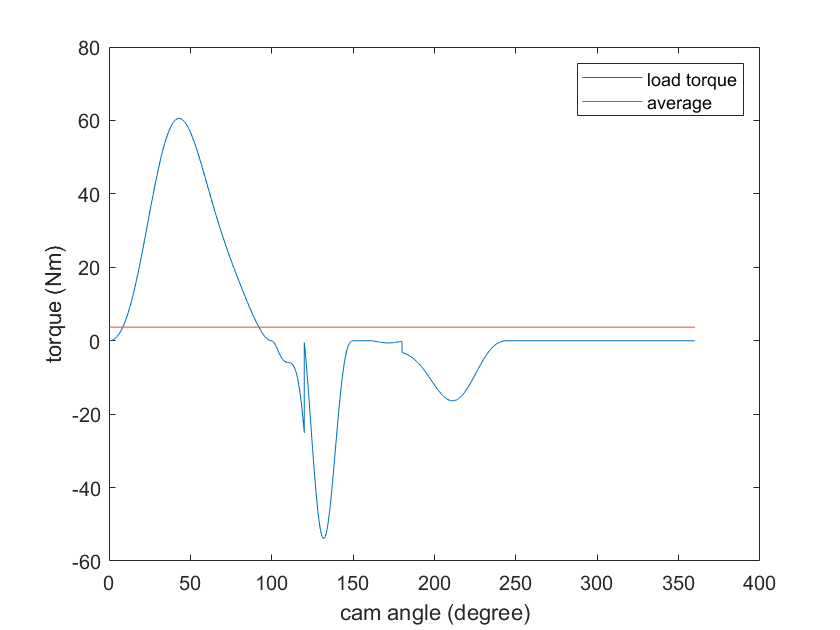


figure
plot(out.thetadegree, M, out.thetadegree,ones(size(out.theta)) * M_av)

xlabel('cam angle (degree)')
ylabel('torque (Nm)')
legend({'load torque','average'})

% speed variation berekenen met formule voor A 
A = cumtrapz(out.theta, M_delta)

A =          0    0.0006    0.0013    0.0019    0.0026    0.0032    0.0039    0.0045    0.0052    0.0058    0.0065    0.0071    0.0078    0.0084    0.0091    0.0097    0.0104    0.0110    0.0116    0.0123    0.0129    0.0136    0.0142    0.0149    0.0155    0.0162    0.0168    0.0175    0.0181    0.0188    0.0194    0.0200    0.0207    0.0213    0.0220    0.0226    0.0233    0.0239    0.0246    0.0252    0.0259    0.0265    0.0272    0.0278    0.0284    0.0291    0.0297    0.0304    0.0310    0.0317


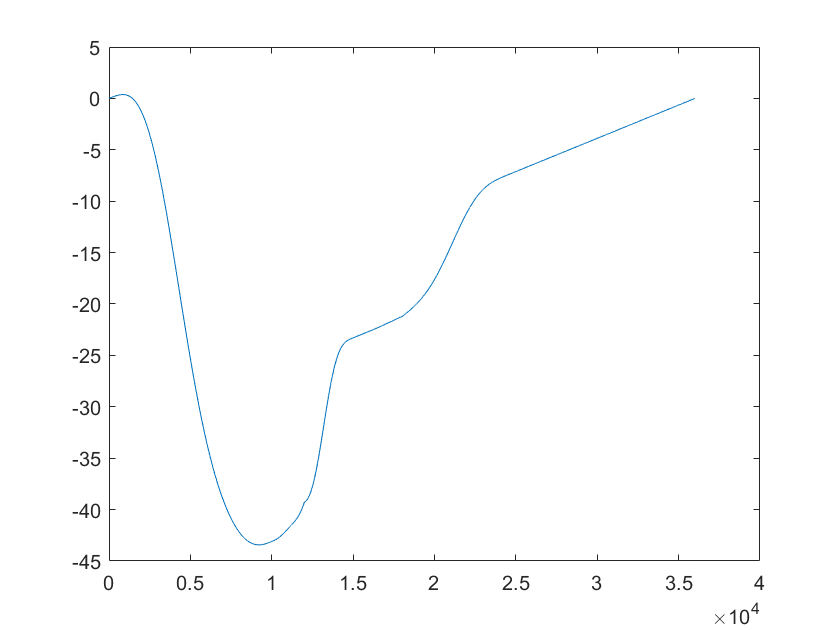

figure
plot(A)

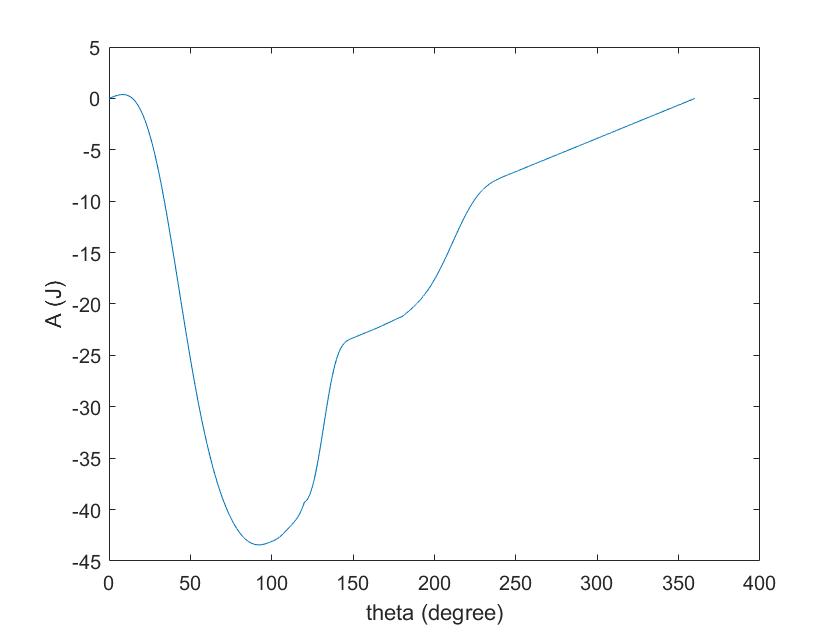


figure
plot(out.thetadegree, A)

xlabel('theta (degree)')
ylabel('A (J)')

%maximum work surplus berekenen: 
[A_max,I_Amax] = max(A)

A_max = 0.3750

I_Amax = 848

[A_min,I_Amin] = min(A)

A_min = -43.4291

I_Amin = 9207

A_maxvar = A_max - A_min

A_maxvar = 43.8041

B2 = out.thetadegree(I_Amin)

B2 = 92.0600

B1 = out.thetadegree(I_Amax)

B1 = 8.4700


%via benadering
b = B2 - B1

b = 83.5900

h = max(M)-M_av

h = 56.8369

A_ben = b*h/2*2*pi/360

A_ben = 41.4603


% massatraagheidsmoment berekenen
I = A_maxvar / (K*out.w^2)

I = 0.1110


%vliegwiel dimensioneren (schijftype)
rho =   7700 % kg/m^3 voor stainless steel

rho = 7700

r = 110*10^(-3) % ietsje kleiner dan basisstraal

r = 0.1100

t = 2*I / (pi*rho*r^4)

t = 0.0627


%I opnieuw berekenen
I2 = pi*r^4*t*rho/2

I2 = 0.1110